# Honours Live Script 1

## Load and Save Data

if ~exist("workspaceVarHonours", 'var')
    load matlabHonours.mat
    setInterpLatex()
end

if exist("workspaceVarHonours", 'var')
    clearVarsArray = clearVars();
    clear(clearVarsArray{:})
    clear clearVarsArray
    save matlabHonours.mat
end 

% set the default intepreter to latex
setInterpLatex()

## Contents

Assumptions Made

Time Series Autocorrelation Coding

Time Series Covariance Matrix Coding

Beverton - Holt Model Coding

Average - CV PE and Mean - Variance PE Coding

## Assumptions Made

## Time Series Autocorrelation Coding

% need to figure out a method which can simulate time - series data which
% has different levels of synchrony between them -> maybe should ask Mike
% about this -> grabbing code from MXN423 so that I can instead then
% simulate stochastic time - series data using the discrete time Beverton -
% Holt model

% idea - write a method which can generate a number of time series data,
% each with their own mean and variance, and a covariance matrix between
% them

% this will be kinda tricky I think, so gonna math it out on paper first,
% but for now it will at a base level just run the discrete time Beverton -
% Holt model -> wait - this might have an upward bias, but like also we
% need a correlation between sequential values

% idea is this: at a base level with 0 correlation, will just generate n
% different time series data, each with their own mean, variance and auto -
% correlation

% might be easier instead to just figure out a way to simulate data which
% has a set level of time - series correlation, 

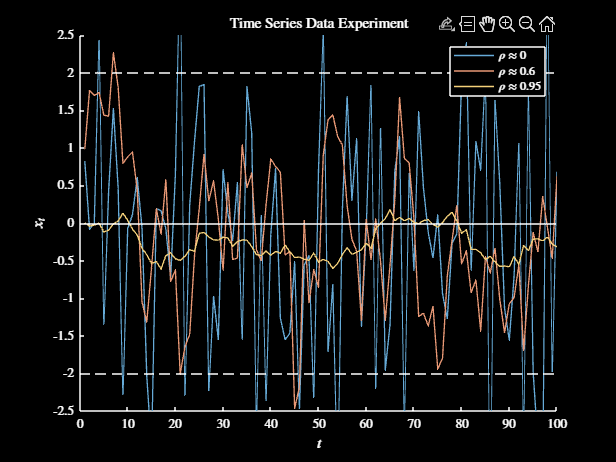

% create the autocorrelation here - thinking about doing so in a maybe
% strange way, but let's see if it pays off
tMax = 100;
mu = 0;
sigma = 1;
autoCorrVec = [0, 0.6, 0.95];
tSMat = timeSeriesSim(mu, sigma, tMax, autoCorrVec);

% plot the results
figure
hold on
lgndCell = cell(1, length(autoCorrVec));
for c = 1:length(autoCorrVec)
    plot(1:tMax, tSMat(c, :), 'LineWidth', 1)
    lgndCell{c} = sprintf("$\\rho \\approx %g$", autoCorrVec(c));
end
yline(mu, 'k')
yline(mu + 2 * sigma, 'k--')
yline(mu - 2 * sigma, 'k--')
xlabel("$t$")
ylabel("$x_{t}$")
title("Time Series Data Experiment")
legend(lgndCell)
ylim([mu - 2.5 * sigma, mu + 2.5 * sigma])
darkFig()


% calculate the correlations of the above entries
autoCorrRes = zeros(1, length(autoCorrVec));
for i = 1:length(autoCorrVec)
    autoCorrRes(i) = corr(tSMat(i, 1:(end - 1))', tSMat(i, 2:end)');
end
autoCorrRes

autoCorrRes =    -0.1479    0.7071    0.9076


% I want to use good ol Monte - Carlo to determine a relationship between
% the auto - correlation factor I'm using above, and the actual auto -
% correlation observed above

% setup a vector of values for my factor to use
corrFactVec = linspace(0, 1, 10000);

% simulate 25 time series data for each of the factors above, each time
% series will go for 50 timesteps
mu = 0;
sigma = 1;
nReps = 1;
tMax = 50;

% loop over, and store the results from each of the trials
resMat = zeros(1, length(corrFactVec));
for i = 1:length(corrFactVec)

    % simulate nReps time series for this level of correlation then
    % calculate the observed autocorrelation
    tSMat = timeSeriesSim(mu, sigma, tMax, corrFactVec(i));
    resMat(i) = corr(tSMat(1:(end-1))', tSMat(2:end)');

end

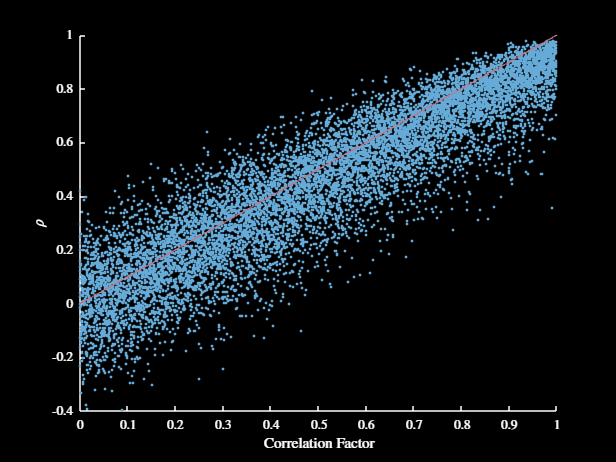

% visualise the results
figure
hold on
plot(corrFactVec, resMat, '.', 'Color', getColour('b'))
plot(corrFactVec, corrFactVec, 'Color', getColour('r'))
xlabel("Correlation Factor")
ylabel("$\rho$")
darkFig()


% this is kinda cool, because it appears that there is more or less a
% linear relationship between my correlation factor thing and the actual
% autocorrelation which is cool and good I think - should probably fit a
% linear model to the data above but I'm lazy so idk if I can be bothered

% check just for the sake of completeness:
linModFit = fitlm(corrFactVec, resMat);
linModFit.Coefficients

ans = 2×4 table
                   Estimate        SE         tStat       pValue  
                   _________    _________    _______    __________

    (Intercept)    -0.012376    0.0024576    -5.0358    4.8428e-07
    x1               0.91267     0.004257     214.39             0



% yep, it appears that my assumption of a perfect linear relationship
% between these variables seems relatively reasonable which is cool and
% good

## Time Series Covariance Matrix Coding

% now need to be able to generate time series data with correlations
% between the different time series

% gonna go read a blog post - ey thing about it first, but seems pretty
% cool tbh - might need to think about generating a bunch of standardised
% normal variables first for each, and then multiplying by the actual
% assigned standard deviations of the variables and adding the means

% wait - can do this after - first, just need to generate a standard normal
% variable for each time series, take a linear combination based on the
% correlation matrix, then after the linear combination scale for each of
% the separate time series - damn this is kinda cool idea methinks

% first, let's see if my assumption about mvnrnd()'s variance is going to
% be reasonable
corrMat = [1, -0.95; -0.95, 1];
sigmaVec = [10, 1]';
covMat = sigmaVec * sigmaVec' .* corrMat

covMat =   100.0000   -9.5000
   -9.5000    1.0000


obsMat = mvnrnd([0, 0], covMat, 100);

% check that the above has actually worked
std(obsMat(:, 1))

ans = 10.6220

std(obsMat(:, 2))

ans = 1.1252


% perfect - it appears that even when we have some correlation going on,
% the variables still end up retaining their set standard deviation in this
% format
corr(obsMat(:, 1), obsMat(:, 2))

ans = -0.9658


% this is very cool and good, can now go ahead and look at writing this
% into my code for the time series

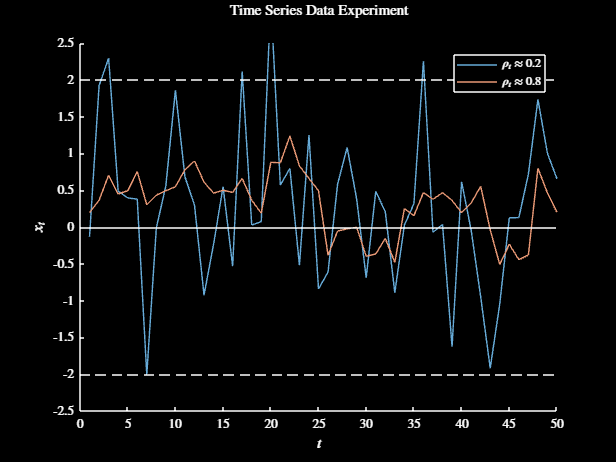

% wrap the above plus more into a function and run it
mu = 0;
sigma = 1;
tMax = 50;
rho = 0.6;
autoCorrVec = [0.2, 0.8];
corrMat = [1, rho; rho, 1];
tSMat = timeSeriesSim(mu, sigma, tMax, autoCorrVec, corrMat);

% now, visualise the results
figure
hold on
lgndCell = cell(1, length(autoCorrVec));
for c = 1:length(autoCorrVec)
    plot(1:tMax, tSMat(c, :))
    lgndCell{c} = sprintf("$\\rho_{t} \\approx %g$", autoCorrVec(c));
end
yline(mu, 'k')
yline(mu + 2 * sigma, 'k--')
yline(mu - 2 * sigma, 'k--')
xlabel("$t$")
ylabel("$x_{t}$")
title("Time Series Data Experiment")
subtitle(sprintf("$\\rho = %g$", rho))
legend(lgndCell)
ylim([mu - 2.5 * sigma, mu + 2.5 * sigma])
darkFig()


% another thing to think about, is how in the current formulation, the
% correlation between time series is probably going to effect the variance
% of each of the time series in turn - this is another trade - off I'm not
% sure how to deal with, but it is good to be aware of

% otherwise, the above appears to be working relatively well, so should see
% if I am able to recover the useful information from the above plots
rho

rho = 0.6000

corr(tSMat(1, :)', tSMat(2, :)')

ans = 0.3597

autoCorr(tSMat)

ans =     0.1712
    0.6533


% I want to repeat the above experiment, but for a large number of
% variables etc to see how adding correlation between time series with
% different autocorrelation affects the time series themselves
mu = [5, 17];
sigma = [1, 3];
tMax = 50;
rho = 0.8;
autoCorrVec = [0.2, 0.8];
corrMat = [1, rho; rho, 1];
nReps = 1000;

% repeat this test 1000 times, and record the observed correlation between
% time series and each time series' autocorrelation, mean and standard
% deviations
rhoObsVec = zeros(1, nReps);
autoCorrObsMat = zeros(2, nReps);
for r = 1:nReps

    % simulate time series and record observed metrics
    tSMat = timeSeriesSim(mu, sigma, tMax, autoCorrVec, corrMat);
    rhoObsVec(r) = corr(tSMat(1, :)', tSMat(2, :)');
    autoCorrObsMat(:, r) = autoCorr(tSMat);

end

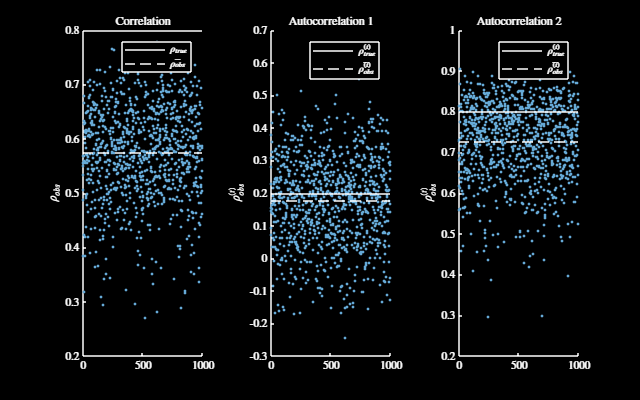

% now plot the results
tiledlayout(1, 3)

% plot the correlation
nexttile
hold on
plot(1:nReps, rhoObsVec, '.')
yline(rho)
yline(mean(rhoObsVec), '--')
ylabel("$\rho_{obs}$")
legend("", "$\rho_{true}$", "$\bar{\rho_{obs}}$")
title("Correlation")

% plot the autocorrelation of the first population
nexttile
hold on
plot(1:nReps, autoCorrObsMat(1, :), '.')
yline(autoCorrVec(1))
yline(mean(autoCorrObsMat(1, :)), '--')
ylabel("$\rho_{obs}^{(t)}$")
legend("", "$\rho_{true}^{(t)}$", "$\bar{\rho_{obs}^{(t)}}$")
title("Autocorrelation 1")

% plot the autocorrelation of the second population
nexttile
hold on
plot(1:nReps, autoCorrObsMat(2, :), '.')
yline(autoCorrVec(2))
yline(mean(autoCorrObsMat(2, :)), '--')
ylabel("$\rho_{obs}^{(t)}$")
legend("", "$\rho_{true}^{(t)}$", "$\bar{\rho_{obs}^{(t)}}$")
title("Autocorrelation 2")
figRect(1.5, 1.8)
darkFig()

% need to at some point think about how the initial value affects the
% trajectory of time series with a really high autocorrelation - could
% maybe set the original value as a linear comb of the rv and the
% associated mean

% also need to think about how the autocorrelation affects the actual
% variance of the time series - clearly as the autocorrelation in the
% current model is increased, the overall variance of the time series is
% decreased - not sure if it is theoretically possible to remove this kind
% of trade - off

% I've done too much thinking for the time being, so just gonna go and read
% some papers before coming back to this

## Beverton - Holt Model Coding

% throw down the constant values - note that this model is quite sensitive
% to these parameters
a = 2;
b = 0.01;
sigma = 0.15;
tMax = 70;

% can calulate here the equilibrium population
nInf = -(1 - a) / b

nInf = 100

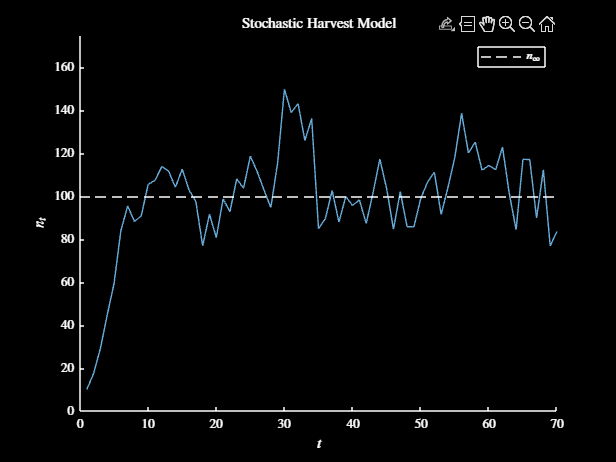

nMax = ceil(1.75 * nInf);

% create anonymous functions for the states at each time
ntPlus1 = @(nt) lognrnd(0, sigma) * a * ...
    nt / (1 + b * nt);

% setup the initial population
nVec = zeros(1, tMax);
nVec(1) = 0.1 * nInf;

% simulate over time
for t = 2:tMax
    nVec(t) = ntPlus1(nVec(t-1));
end

% plot the results
figure
hold on
plot(1:tMax, nVec)
yline(nInf, '--')
xlabel("$t$")
ylabel("$n_t$")
title("Stochastic Harvest Model")
legend("", "$n_{\infty}$")
ylim([0, nMax])
xlim([0, tMax])
darkFig()

% I want to now see what the mean population is if we start at the
% equilibrium population, and let things just screw around, as a function
% of sigma
sigmaVec = linspace(0, 0.15, 15000 / 2 + 1);
tMax = 220;
tWarmup = 20;
muVec = zeros(1, length(sigmaVec));
sdVec = zeros(1, length(sigmaVec));
ntPlus1 = @(nt, sigma) lognrnd(0, sigma) * a * ...
    nt / (1 + b * nt);

% iterate the Beverton - Holt model for 110 timesteps, with a 10 timestep
% warmup period, then record the mean and standard deviation of the time
% series
for s = 1:length(sigmaVec)

    % simulate the population
    nVec(1) = nInf;
    for t = 2:tMax
        nVec(t) = ntPlus1(nVec(t-1), sigmaVec(s));
    end

    % record the statistics of interest after the warmup period
    muVec(s) = mean(nVec(tWarmup:tMax));
    sdVec(s) = std(nVec(tWarmup:tMax));

end

% let's look at the mean of these values
mean(muVec)

ans = 8.5058

mean(muVec(6000:end))

ans = 0


% other methods didn't work so I'm just gonna calculate this problem using
% good ol' Markov chains because I'm an absolute madlad
[ntExp, ntVar] = meanVarBH(a, b, 0.15)

ntExp = 100.6961

ntVar = 300.7672

ntSD = sqrt(ntVar)

ntSD = 17.3426


% let's make predictions based on the range of sigma values using my above
% Markov chain approach, and compare to the Monte - Carlo observations
mChainSigma = linspace(0, 0.15, 101);
mChainMean = zeros(1, length(mChainSigma));
mChainSD = zeros(1, length(mChainSigma));
mChainSS = cell(1, length(mChainSigma));

% check the computation times between the two approaches for calculating
% the steady state probability vector
tic
for i = 1:length(mChainSigma)
    [mChainMean(i), mChainSD(i), mChainSS{i}] = meanVarBH(a, b, ...
        mChainSigma(i), [], "iter");
end
toc

Elapsed time is 85.225049 seconds.



% the above took 76 seconds

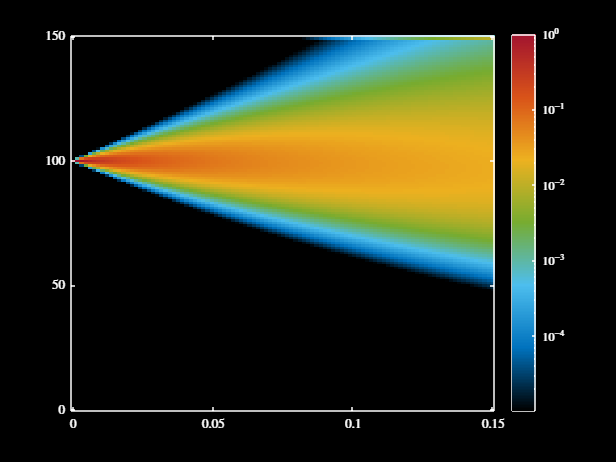

% let's have a look at the good ol steady state vectors to see what's up
nStates = length(mChainSS{1});
ntSSMat = zeros(nStates, length(mChainSigma));
for i = 1:length(mChainSigma)
    ntSSMat(:, i) = mChainSS{i};
end

figure
imagesc(mChainSigma, 0:(length(ntSSMat) - 1), ntSSMat)
set(gca, 'ydir', 'normal')
colormap(myColourMap)
colorbar
set(gca, 'colorscale', 'log')
darkFig()

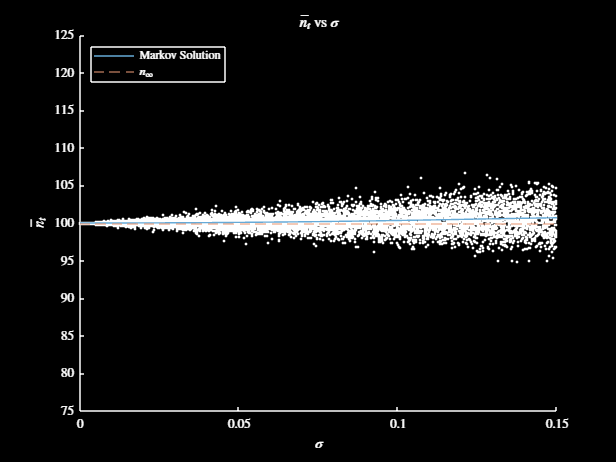

% plot the results
figure
hold on
plot(sigmaVec, muVec, 'k.')
yline(nInf, '--', 'color', getColour('o'))
plot(mChainSigma, mChainMean, 'color', getColour('b'))
xlabel("$\sigma$")
ylabel("$\bar{n_t}$")
title("$\bar{n_t}$ vs $\sigma$")
legend("", "$n_{\infty}$", "Markov Solution", 'location', ...
    'northwest')
ylim([0.75 * nInf, 1.25 * nInf])
darkFig()


% seems realistic enough to posit that the mean is approximately the true
% equilibrium population more or less, however there appears to be a slight
% upward drift as sigma increases

% gonna fit a linear model and plot it as well
fitModel = fitlm(sigmaVec, sdVec);

% can also extract the parameters as follows
beta0 = fitModel.Coefficients{1, "Estimate"}

beta0 = -0.0274

beta1 = fitModel.Coefficients{2, "Estimate"}

beta1 = 115.6926

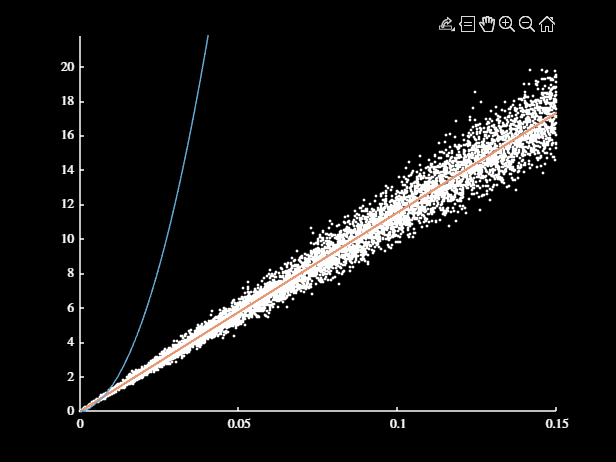


% let's also add in some estimations of the standard deviation using my

% let's now plot the standard deviation as a function of the sigma
% parameter
figure
hold on
plot(sigmaVec, sdVec, 'k.')
plot(sigmaVec, beta0 + beta1 * sigmaVec, '-', 'color', getColour('o'), ...
    'LineWidth', 2)
plot(mChainSigma, mChainSD, 'color', getColour('b'))
% xlabel("$\sigma$")
% ylabel("$sd_{n_{t}}$")
% title("$sd_{n_{t}}$ vs $\sigma$")
% legend("Monte - Carlo Results", "Linear Regression", ...
% "Markovian Solution", 'location', 'northwest')
ylim([0, 1.1 * max(sdVec)])
darkFig()


% this is not good lmao, clearly my methods have some issues which need
% addressing so I'm glad I checked them

% find the weird value's corresponding sigma
ind = find(mChainMean1 < 0)

ind = 87

mChainSigma(ind)

ans = 0.1290

% see if I can recreate the above relationship between sigma and the
% standard deviation of the population using my Markov chain approximation

% welp this is cool and good - looks like the mean population is equal to
% the carrying capacity with a bit of variance towards the end, and that
% there appears to be a linear relationship between the observed standard
% deviation and the sigma parameter, so that's cool

% one thing to note however, is that this is only using a certain magnitude
% of sigma values, along with the fact that due to the shape of a lognormal
% distribution, we'll probably have a skew towards the higher values which
% would be more apparent the higher the sigma I think

## Correlated Beverton - Holt Model Coding

% need to think here about how to correlate the models together, given they
% have different means and variances each - maybe a decent idea is to
% standardise the populations before taking linear combinations, before
% then scaling back up

% it is also important to 

% wait - probably don't want to bother coding up these jussssst yet as
% maybe it's a good idea to first think about how connectivity is involved
% rather than coding up a maybe useless method

% as a result, gonna leave this for now

% forget about this for now lmao -> realistically for the toy model at
% this point it would be nice to just use the good ol' normal distribution
% stuff I did earlier

## Average - CV PE and Mean - Variance PE Coding

% gonna code up the PE metrics described in the ecological prophets paper
% create some test data first, and then mess around with the metrics
means = unifrnd(0, 1000, [50, 1]);
vars = 0.2 * (means + 0.1 * mean(means) * normrnd(0, 1, size(means))).^2;

% fit a model to the logged mean and variance scales
fitModel = fitlm(log(means), log(sqrt(vars)));

% can also extract the parameters as follows
beta0 = fitModel.Coefficients{1, "Estimate"};
beta1 = fitModel.Coefficients{2, "Estimate"};

% check to see that I've done this right, by plotting the log - log
% results
figure
hold on
plot(log(means), log(sqrt(vars)), '.')
plot([min(log(means)), max(log(means))], 2 * [min(log(means)), ...
    max(log(means))] + log(0.2) / 2)
plot(log(means), predict(fitModel, log(means)))
xlabel("$log(\mu)$")
ylabel("$log(\sigma)$")
legend("", "$z = 2$ line", "Fitted $z$ Relationship", 'Interpreter', ...
    'latex', 'Location', 'northwest')
title("Mean - Variance Scaling Plot")
subtitle(sprintf("Fitted $z=%g$", round(beta1, 3)))
darkFig()

## Metapopulation Base Model

% going to code up a base model for the metapopulation, which can maybe
% take in the species specific parameters and run the model, and so could
% be wrapped in parent functions for each different case stufy
% baseMetapopModel()

% let's check if my methods are working with some parameters chosen from
% the original Bode et al., and others simply chosen for simplicity for
% visualisation

% look at Mike's parameters here for some inspiration on fecundity
sizeVec = 52.2 * (1 - exp(-0.354 * (1:14 + 0.766)))

sizeVec =    15.5621   26.4848   34.1511   39.5320   43.3086   45.9594   47.8199   49.1257   50.0422   50.6855   51.1370   51.4539   51.6763   51.8325


fecundVec = 13.82 * sizeVec.^3.03

fecundVec = 1.0e+06 *

    0.0566    0.2833    0.6120    0.9534    1.2570    1.5049    1.6972    1.8415    1.9476    2.0244    2.0796    2.1189    2.1468    2.1665


massVec = 0.0079 * sizeVec

massVec =     0.1229    0.2092    0.2698    0.3123    0.3421    0.3631    0.3778    0.3881    0.3953    0.4004    0.4040    0.4065    0.4082    0.4095


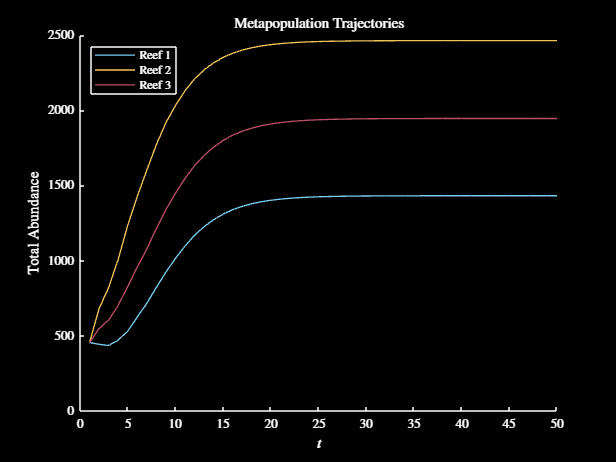

% now set some of my own parameters and just hope for the best, will use a
% 3 reef metapopulation model so that I can kind of pretty easily see
% what's going on
specStruct.alpha = 1.5 * 10^-5;
specStruct.beta = 1 * 10^-8;
specStruct.successVec = [0.65, 0.7, 0.8];
specStruct.fecundVec = 10^5 * [0, 2, 4, 6];
areaVec = [1, 1, 1];

% let's start with uniform populations across the reefs, that way we can
% really see how the system equilibrium turns out
unifPop = [200, 100, 80, 75];
popInit = repmat(unifPop, [3, 1]);
conMat = [0.05, 0.007, 0.001; 0.09, 0.3, 0.09; 0, 0.09, 0.15];

% let's run this for like idk 50 years and play around with things and see
% what happens -> want to make sure the system behaves as expected
tMax = 50;
popMat = baseMetapopModel(conMat, areaVec, popInit, tMax, specStruct);

% visualise the stuff -> create a function
visualiseMetapop(popMat, 1:tMax)
darkFig()

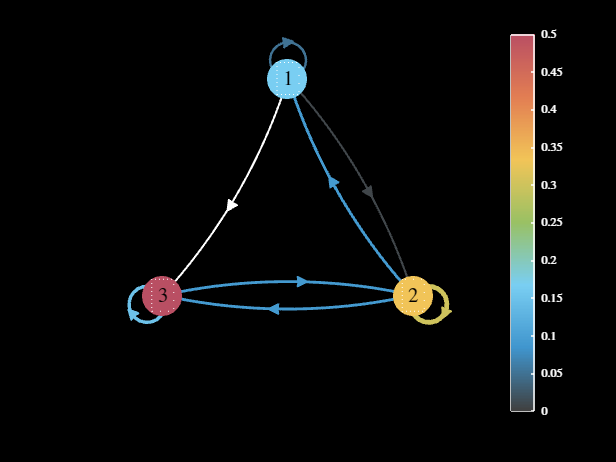

% write a function which can visualise the connectivity matrix nice and
% easily, so that I can have a quick visual aid
conMatTest = conMat;
% conMatTest = diag(diag(conMatTest));
% conMatTest(1, 2) = 0.5;
% % conMatTest(2, 1) = 0.5;
% % conMatTest(3, 1) = 0.5;
% conMatTest(1, 3) = 0.5;
visualiseConMat(conMatTest)
darkFig()


% something is up with my figure above what da hell

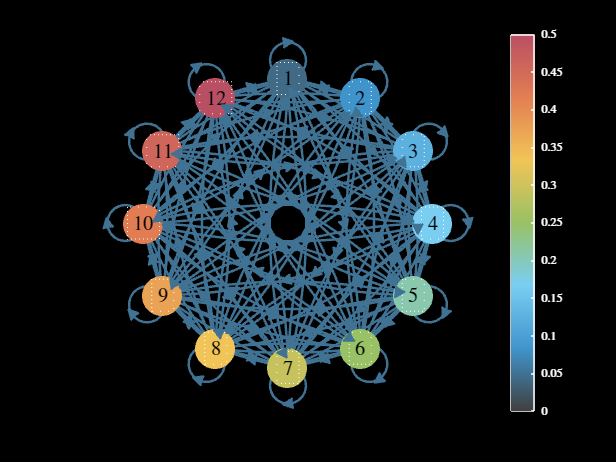

% make a cool picture because I'm bored
nPoints = 12;
conMatTest = 0.05 * (unifrnd(0, 0.5, nPoints, nPoints) > 0);
visualiseConMat(conMatTest)
darkFig()